# `First-order systems analysis`

`A program to quickly and easily solve and analyse first order systems`

`Created by Sam Scott on 18/05/22`

`Includes:`

`Open loop control analysis`

- `Step response`

- `Numerical Step info`

- `DC gain calculation`

- `Poles and zeros`

- `Frequency response with bandwidth calculation`

`Closed loop control analysis`

- `Above and`

- `PID controller input`

- `Sensitivity analysis.`

#### `Setup`

s = tf('s');


% Plant transfer function 
numerator = 1; % replace as appropriate
A = 2;   % Replace coefficients as appropriate
B = 2;
denominator = ( (A)*s + (B) ); 
G = (numerator / denominator)

## `Open loop control`

#### 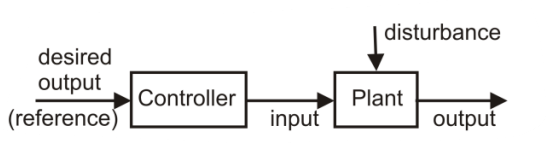

% Open loop control analysis
fprintf("\n\nOpen Loop control:\n-------------------------------------------------");

% Controller
openLoopController = 1; % change as appropriate

oLT = (openLoopController*G) % open loop transfer function

% Step response
stepMagnitude = 1;
openLoopStep = step(oLT*stepMagnitude);
step(oLT*stepMagnitude)
title("Open loop step response")

% numerical step info
openLoopNumericalStepInfo = stepinfo(oLT*stepMagnitude)


openLoopDCGain = dcgain(oLT)

[openLoopPoles, openLoopZeros] = pzmap(oLT)


% Frequency analysis
fprintf("---------------------------------------\n\nOpen loop frequency response\n\n")
%omega = logspace(0, 100, 10000);
h = bodeplot(oLT);
title("Open loop frequency response")
% For absolute units in Hz:
%setoptions(h,'FreqUnits','Hz','MagUnits', 'Abs');

% For absolute units in rad/s
setoptions(h, 'MagUnits', 'Abs')

grid on


% Finding bandwidth
bw = bandwidth(oLT);
fprintf("\nBandwidth: %f (rad/s) == %f (Hz)\n\n\n\n\n\n\n------------------------------------------------", bw, (bw/(2*pi)))


## `Closed loop control`

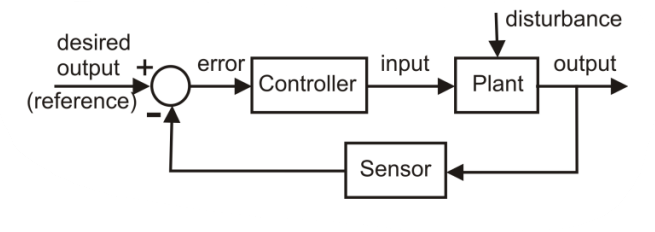

% Closed loop control analysis - Plant: G
fprintf("\n\nClosed Loop control: CHECK THAT ITS SECOND ORDER\n-------------------------------------------------");

% Controller - PID
Kp = 1; % change as appropriate
Ki = 0;
Kd = 0;
closedLoopController = Kp + Ki/s + s*Kd; 

% assuming unity feedback
cLT = (feedback(closedLoopController*G, 1)) % closed loop transfer function

% Step response
stepMagnitude = 1;
closedLoopStep = step(cLT*stepMagnitude);
step(cLT*stepMagnitude)
title("Closed loop step response")
% numerical step info
closedLoopNumericalStepInfo = stepinfo(cLT*stepMagnitude)


closedLoopDCGain = dcgain(cLT)

[closedLoopPoles, closedLoopZeros] = pzmap(cLT)


% Frequency analysis
fprintf("---------------------------------------\n\nClosed loop frequency response\n\n")
%omega = logspace(0, 100, 10000);
h = bodeplot(cLT);
title("Closed loop frequency response")

% For absolute units in Hz:
%setoptions(h,'FreqUnits','Hz','MagUnits', 'Abs');

% For absolute units in rad/s
setoptions(h, 'MagUnits', 'Abs')

grid on


% Finding bandwidth
bw = bandwidth(cLT);
fprintf("\nBandwidth: %f (rad/s) == %f (Hz)", bw, (bw/(2*pi)))


% Sensitivity analysis

fprintf("¬\n\n\n\n\n\nSensitivity Analysis -----------------------")
S = 1/(1+cLT*G) % S = Y(S)/V(s)

sensitivity = bodeplot(S);
title("Closed loop Sensitivity Analysis")
% For absolute units in Hz:
setoptions(sensitivity,'FreqUnits','Hz','MagUnits', 'Abs');


% For absolute units in rad/s
%setoptions(sensitivity, 'MagUnits', 'Abs')
grid on

DCsensitivityGain = dcgain(S)
[Gm,Pm,Wcg,Wcp] = margin(S);
gainCrossoverFreq = Wcp; % gain crossover frequency
fprintf("Gain crossover frequency: %f (rad/s) == %f (Hz)", gainCrossoverFreq, (gainCrossoverFreq/(2*pi)))






